# Derivative

## Definition

(SB) Let $(x_0, f(x_0))$ be a point on te graph of $y=f(x)$.

The **derivative** of $f$ at $x_0$ is  the slope of the tangent line to the graph of $f$ at $(x_0, f(x_0))$.

There are some common ways of denoting derivative of funtion $f$ at $x_0$:

- 
$$f'(x_0)$$


- 
$$\frac{df}{dx} (x_0)$$


- 
$$\frac{dy}{dx} (x_0)$$


- $f_x(x_0)$: this is popular in economics

We write this analyticaly as:


$$f'(x_0) = \lim_{h\rightarrow 0} \frac{f(x_0 + h) - f(x_0)}{h}$$


If this limit exists, then the function $f$ is **differentiable** at $x_0$.

## MPK Average Output Per Additional Worker

Let's consider a cobb-douglas production function again. 

If you own a firm, you would be very interested in how much additional output you can get from one more unit of capital of one more labor hired. If you know that, you can compare that against the cost of more capital and labor and determine if it is optimal to choose to increase capital and/or labor. 


$$U(K,L) = K^{\alpha} \cdot L^{1-\alpha}$$


For now, let's fix capital. Suppose capital takes a long time to adjust, but labor can be adjusted. You currently have $K=1$ and $L=2$, what happens to output if you increase labor?

The above formula is calculating the average additional output produced by $h$ more workers:

clear all;
% fixed capital level
K = 1;
% current labor level
L = 2;

% Cobb Douglas Production Parameters
alpha = 0.5;
beta = 1-alpha;

% Output at x0
f_x0 = (K^alpha)*(L.^beta);

% a vector of h
h = linspace(0, 14, 100);

% output at f_x0_plus_h
x0_plus_h = L+h;
f_x0_plus_h = (K^alpha)*((x0_plus_h).^beta);

% derivatie 
f_prime_x0 = (f_x0_plus_h - f_x0)./h;

% Show Results in table
T = table(h', x0_plus_h', f_x0_plus_h', f_prime_x0');
T.Properties.VariableNames = {'h', 'x0_plus_h', 'f_x0_plus_h', 'f_prime_x0'};
T

T = 100×4 table
       h       x0_plus_h    f_x0_plus_h    f_prime_x0
    _______    _________    ___________    __________

          0          2        1.4142            NaN  
    0.14141     2.1414        1.4634        0.34752  
    0.28283     2.2828        1.5109        0.34187  
    0.42424     2.4242         1.557        0.33656  
    0.56566     2.5657        1.6018        0.33157  
    0.70707     2.7071        1.6453        0.32685  
    0.84848     2.8485        1.6877        0.32238  
     0.9899     2.9899        1.7291        0.31813  
     1.1313     3.1313        1.7696        0.31409  
     1.2727     3.2727        1.8091        0.31024  
     1.4141     3.4141        1.8477        0.30656  
     1.5556     3.5556        1.8856        0.30305  
      1.697      3.697        1.9228        0.29967  
     1.8384     3.8384        1.9592 

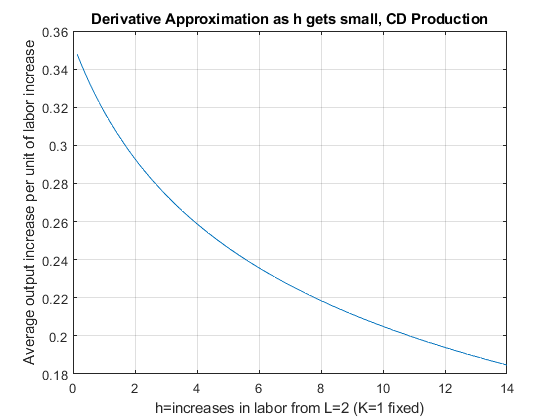


% Graph
close all;
figure();
plot(h, f_prime_x0);
grid on;
ylabel('Average output increase per unit of labor increase')
xlabel('h=increases in labor from L=2 (K=1 fixed)')
title('Derivative Approximation as h gets small, CD Production')

## Marginal Product of Additional Workers (Discrete Workers)

Suppose we can not hire fractions of workers, but have to hire 1, 2, 3, etc.. What is the marginal product of each additional worker?

% fixed capital level
K = 1;
% current labor level
L = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15];

% Cobb Douglas Production Parameters
alpha = 0.5;
beta = 1-alpha;

% Output at x0
f_x0 = (K^alpha)*(L.^beta);

% a vector of h
h = 1;

% output at f_x0_plus_h
x0_plus_h = L+h;
f_x0_plus_h = (K^alpha)*((x0_plus_h).^beta);

% derivatie 
f_prime_x0 = (f_x0_plus_h - f_x0)./h;

% Show Results in table
T = table(L', x0_plus_h', f_x0_plus_h', f_prime_x0');
T.Properties.VariableNames = {'L', 'x0_plus_h', 'f_x0_plus_h', 'f_prime_x0'};
T

T = 15×4 table
    L     x0_plus_h    f_x0_plus_h    f_prime_x0
    __    _________    ___________    __________

     1        2          1.4142        0.41421  
     2        3          1.7321        0.31784  
     3        4               2        0.26795  
     4        5          2.2361        0.23607  
     5        6          2.4495        0.21342  
     6        7          2.6458        0.19626  
     7        8          2.8284        0.18268  
     8        9               3        0.17157  
     9       10          3.1623        0.16228  
    10       11          3.3166        0.15435  
    11       12          3.4641        0.14748  
    12       13          3.6056        0.14145  
    13       14          3.7417        0.13611  
    14       15           3.873        0.13133  
    15       16               4        0.12702  


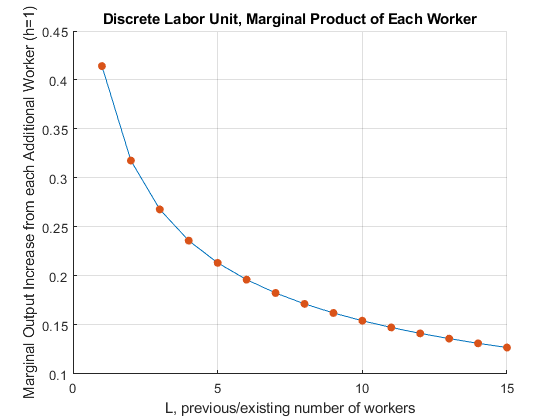


% Graph
close all;
figure();
hold on;
plot(L, f_prime_x0);
scatter(L, f_prime_x0,'filled');
grid on;
ylabel('Marginal Output Increase from each Additional Worker (h=1)')
xlabel('L, previous/existing number of workers')
title('Discrete Labor Unit, Marginal Product of Each Worker')

## Marginal Product of Additional Workers Different Capital (Discrete Workers)

Suppose we can not hire fractions of workers, but have to hire 1, 2, 3, etc.. What is the marginal product of each additional worker?

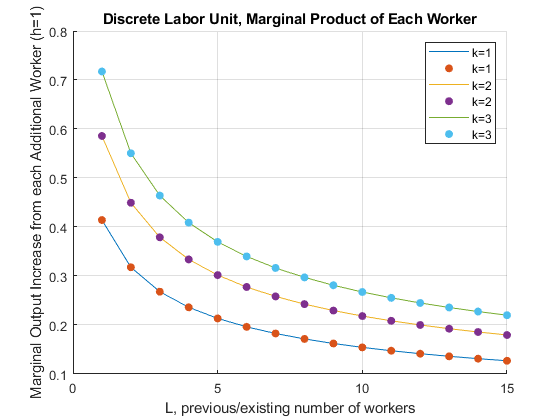

% fixed capital level
K1 = 1;
[f_prime_x0_K1, L] = MPKdiscrete(K1);
K2 = 2;
[f_prime_x0_K2, L] = MPKdiscrete(K2);
K3 = 3;
[f_prime_x0_K3, L] = MPKdiscrete(K3);

% Graph
close all;
figure();
hold on;
plot(L, f_prime_x0_K1);
scatter(L, f_prime_x0_K1,'filled');
plot(L, f_prime_x0_K2);
scatter(L, f_prime_x0_K2,'filled');
plot(L, f_prime_x0_K3);
scatter(L, f_prime_x0_K3,'filled');
grid on;
ylabel('Marginal Output Increase from each Additional Worker (h=1)')
xlabel('L, previous/existing number of workers')
title('Discrete Labor Unit, Marginal Product of Each Worker')
legend(['k=',num2str(K1)], ['k=',num2str(K1)],...
    ['k=',num2str(K2)],['k=',num2str(K2)],...
['k=',num2str(K3)],['k=',num2str(K3)]);

function [f_prime_x0, L] = MPKdiscrete(K)
% current labor level
L = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15];

% Cobb Douglas Production Parameters
alpha = 0.5;
beta = 1-alpha;

% Output at x0
f_x0 = (K^alpha)*(L.^beta);

% a vector of h
h = 1;

% output at f_x0_plus_h
x0_plus_h = L+h;
f_x0_plus_h = (K^alpha)*((x0_plus_h).^beta);

% derivatie 
f_prime_x0 = (f_x0_plus_h - f_x0)./h;

end